Домашняя работа по теме "Полиномы"

Кабанов Степан

Номер 1.

(Задать полином р(х) и найти графически его корень)

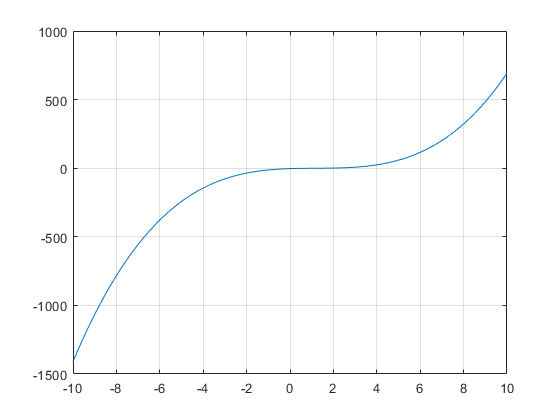

p = [1, -3.55, 5.1, -3.1]; 
x = linspace(-10,10,100);
F = polyval(p, x);
plot(x, F);
grid on;

format short;
R = roots(p);
disp(R)

   1.5500 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i



Номер 2.

Разделить полиномы.

f1 = [2, -3, 4, -5, 6];
f2 = [1, -3, 1];
g1 = [1, -3, -1, -1];
g2 = [3, -2, 1]

g2 =      3    -2     1


[q1, r1] = deconv(f1, g1)

q1 =      2     3


r1 =      0     0    15     0     9


[q2, r2] = deconv(f2, g2)

q2 = 0.3333

r2 =          0   -2.3333    0.6667


Номер 3.

Пользуясь схемой Горнера вычислить значение полинома f(x) и его производной при х = х0. Проверить правильность значений.

f1 = [1, -2, 6, -10, 16]

f1 =      1    -2     6   -10    16


f2 = [1, 1+2i, 0, -(1+3i), 0, 7];
f3 = [1, -4, 6, -8, 10];
f4 = [1, -3i, -4, 5i, -1];

Поиск значения и производной в точке по схеме Горнера сводится к делению полинома на (х - х0). Остаток от деления - значение полинома, а частное - его производная.

x0 = 3;
g = [1, x0];

[q, r] = deconv(f1, g)

q =      1    -5    21   -73


r =      0     0     0     0   235


q(length(q))

ans = -73

r

r =      0     0     0     0   235


[q, r] = deconv(f2, g)

q =    1.0000 + 0.0000i  -2.0000 + 2.0000i   6.0000 - 6.0000i -19.0000 +15.0000i  57.0000 -45.0000i


r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


q(length(q))

ans = 57.0000 - 45.0000i

r

r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


[q, r] = deconv(f2, g)

q =    1.0000 + 0.0000i  -2.0000 + 2.0000i   6.0000 - 6.0000i -19.0000 +15.0000i  57.0000 -45.0000i


r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


q(length(q))

ans = 57.0000 - 45.0000i

r

r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


[q, r] = deconv(f2, g)

q =    1.0000 + 0.0000i  -2.0000 + 2.0000i   6.0000 - 6.0000i -19.0000 +15.0000i  57.0000 -45.0000i


r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


q(length(q))

ans = 57.0000 - 45.0000i

r

r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.6400 + 1.3500i


Номер 4.

Найти кратные корни полинома, построить график на отрезке, содержащем корни.

f(x) = х^(2n) - nx^(n+1) + nx^(n-1) - 1

n = 5;
p = zeros([1, 2*n]);
p(1) = 1;
p(n+1) = -n;
p(n-1) = n;
p(2*n) = -1;
roots(p)

ans =    0.8017 + 1.6330i
   0.8017 - 1.6330i
  -1.3066 + 0.1801i
  -1.3066 - 0.1801i
   1.0000 + 0.0000i
  -0.4106 + 0.4975i
  -0.4106 - 0.4975i
   0.4156 + 0.4947i
   0.4156 - 0.4947i


Номер 5.

Разложить на простейшие дроби.

1)

bx = [1, 0, 0];
a1 = [1, -1];
a2 = [1, 2];
a3 = [1, 3];
ax = conv(a1, a2);
ax = conv(ax, a3);
[r1, p1, K1] = residue(bx, ax);

2)

[r2, p2, K2] = residue([1, 3], conv([1, -1], [1, 0, 1]));

3)

[r3, p3, K3] = residue([1, 0, 1], [1, 0, 0, 0, -1]);

Номер 6.

Построить полином наименьшей степени по таблице. Найти корни этого полинома. Построить график на отрезке, содержащем корни.

1)

n = 11;
x = [1:n+1];
y = x.^-1;
A = zeros([n+1, n+1]);
for i = 1:(n+1)
    for j = 1:(n+1)
        A(i,j) = x(i)^(n+1-j);
    end
end
B = transpose(y);
p = transpose(A^-1 * B);

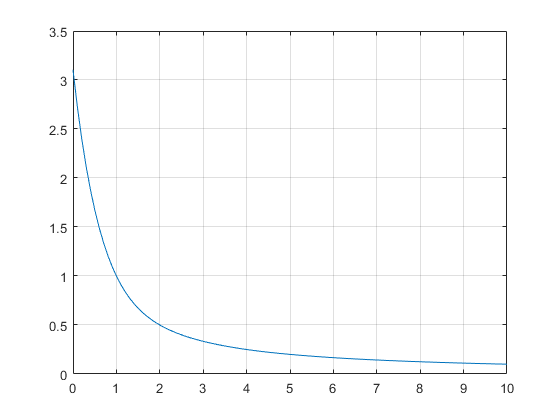


x = linspace(0,10,100);
F = polyval(p, x);
plot(x, F);
grid on;

format short;
R = roots(p);
disp(R)

  13.0000 + 0.0000i
  12.0422 + 2.0091i
  12.0422 - 2.0091i
   9.6471 + 3.6132i
   9.6471 - 3.6132i
   6.5000 + 4.2199i
   6.5000 - 4.2199i
   3.3529 + 3.6132i
   3.3529 - 3.6132i
   0.9578 + 2.0091i
   0.9578 - 2.0091i



2)

x = [-1 0 1 2 3];
y = [6 5 0 3 2];
A = zeros([4, 4]);

for i = 1:5
    for j = 1:5
        A(i,j) = x(i)^(5-j);
    end
end

B = transpose(y);
p = transpose(A^-1 * B)

p =    -1.0000    4.0000   -1.0000   -7.0000    5.0000


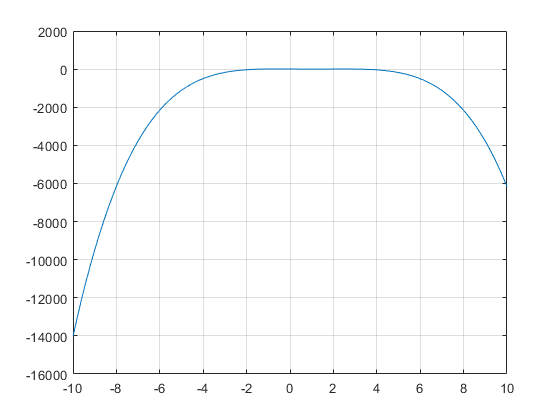


x = linspace(-10,10,100);
F = polyval(p, x);
plot(x, F);
grid on;

format short;
R = roots(p);
disp(R)

    3.1284
   -1.3301
    1.2016
    1.0000



7. Найти корни полиномов и построить график на отрезке содержащем корни.

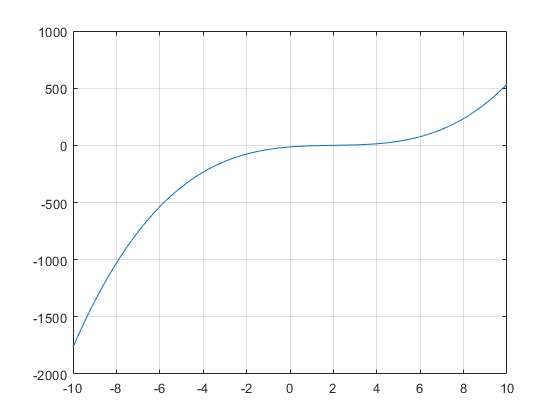

p = [1, -6, 15, -14]; 
x = linspace(-10,10,100);
F = polyval(p, x);
plot(x, F);
grid on;

format short;
R = roots(p);
disp(R)

   2.0000 + 1.7321i
   2.0000 - 1.7321i
   2.0000 + 0.0000i



8. Построить матрицу N*N случайных чисел, построить полином, корнями которого являются собственные значения этой матрицы. Проверить, является ли эта матрица корнем этого полинома.

n = 4;
A = rand([n, n]);

Найдём собственные числа:

[vec, val_] = eig(A);
val = zeros([1,n]);
for i = 1:n
    val(i) = val_(i, i);
end

Построим полином, зная его корни:

r1 = [1, val(i)];
for i=2:n
    r1 = conv(r1, [1, val(i)]);
end
r1

r1 =     1.0000    0.3357   -0.1220   -0.0405    0.0001


9. Найти НОД полиномов и линейное представление.

1)

f = [0 -6 15 -14];
g = [10 13 -15 -18 -24];
[G, S, T] = gcd(g, f)

2)

f = [1 -2 -8 13 -24];
g = [1 2 -13 -38 -24];
[G, S, T] = gcd(f,g)

3)

f = [1 0 -7 -12 6 36];
g = [2 3 -6 -4];
[G, S, T] = gcd(f,g)